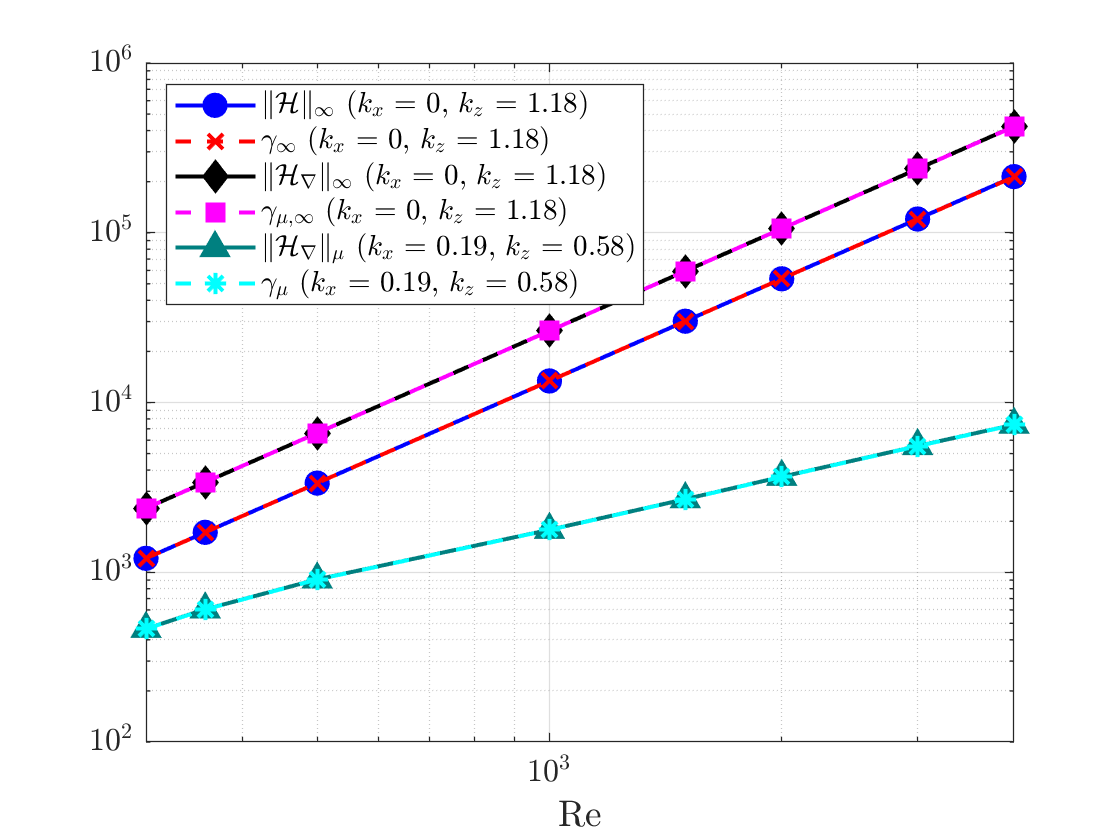

% figure('Color', 'w');
% 
% loglog(Re_list, H_infty_norm, 'b-o', 'LineWidth', 1.5, 'MarkerSize', 8, 'MarkerFaceColor', 'b'); 
% hold on;
% loglog(Re_list, H_infty_norm_LMI_time_independent, 'r--x', 'LineWidth', 1.5, 'MarkerSize', 10);
% loglog(Re_list, H_mu_infty_norm, 'k:*', 'LineWidth', 1.5, 'MarkerSize', 10);
% loglog(Re_list, H_mu_infty_norm_LMI_time_independent, 'y--s', 'LineWidth', 1.5, 'MarkerSize', 10);
% loglog(Re_list, H_mussv_norm, 'k:*', 'LineWidth', 1.5, 'MarkerSize', 10);
% loglog(Re_list, H_mussv_norm_LMI_time_independent, 'y--s', 'LineWidth', 1.5, 'MarkerSize', 10);
% 
% % Formatting the plot
% grid on;
% set(gca, 'FontSize', 12, 'TickLabelInterpreter', 'latex');
% xlabel('Re', 'Interpreter', 'latex', 'FontSize', 14);
% xlim([300 4000]);
% ylim([10^2 10^6])
% % Legend
% legend('$\|\mathcal{H}\|_\infty$ ($k_x$ = 0, $k_z$ = 1.18)', '$\gamma_\infty$ ($k_x$ = 0, $k_z$ = 1.18)', '$\|\mathcal{H}_\nabla\|_\infty$ ($k_x$ = 0, $k_z$ = 1.18)', ...
%     '$\gamma_{\mu,\infty}$ ($k_x$ = 0, $k_z$ = 1.18)','$\|\mathcal{H}_\nabla\|_\mu$ ($k_x$ = 0.19, $k_z$ = 0.58)','$\gamma_\mu$ ($k_x$ = 0.19, $k_z$ = 0.58)',...
%        'Location', 'NorthWest', 'Interpreter', 'latex');



figure('Color', 'w');

% Define line properties
colors  = {'b','r','k','m',[0 0.5 0.5],'c'};
linestyles = {'-','--',':','-.','-','--'};
markers = {'o','x','*','s','^','d'};
markerFaceColors = {'b','r','k','m',[0 0.5 0.5],'c'};

% Plot each dataset
loglog(Re_list, H_infty_norm, ...
    'Color', colors{1}, 'LineStyle', linestyles{1}, 'Marker', markers{1}, ...
    'LineWidth', 1.5, 'MarkerSize', 8, 'MarkerFaceColor', markerFaceColors{1});
hold on;
loglog(Re_list, H_infty_norm_LMI_time_independent, ...
    'Color', colors{2}, 'LineStyle', linestyles{2}, 'Marker', markers{2}, ...
    'LineWidth', 1.5, 'MarkerSize', 8, 'MarkerFaceColor', markerFaceColors{2});

loglog(Re_list, H_mu_infty_norm, ...
    'Color', colors{3}, 'LineStyle', linestyles{1}, 'Marker', markers{6}, ...
    'LineWidth', 1.5, 'MarkerSize', 8, 'MarkerFaceColor', markerFaceColors{3});

loglog(Re_list, H_mu_infty_norm_LMI_time_independent, ...
    'Color', colors{4}, 'LineStyle', linestyles{2}, 'Marker', markers{4}, ...
    'LineWidth', 1.5, 'MarkerSize', 8, 'MarkerFaceColor', markerFaceColors{4});

loglog(Re_list, H_mussv_norm, ...
    'Color', colors{5}, 'LineStyle', linestyles{1}, 'Marker', markers{5}, ...
    'LineWidth', 1.5, 'MarkerSize', 8, 'MarkerFaceColor', markerFaceColors{5});

loglog(Re_list, H_mussv_norm_LMI_time_independent, ...
    'Color', colors{6}, 'LineStyle', linestyles{2}, 'Marker', markers{3}, ...
    'LineWidth', 1.5, 'MarkerSize', 8, 'MarkerFaceColor', markerFaceColors{6});

% Formatting the plot
grid on;
set(gca, 'FontSize', 12, 'TickLabelInterpreter', 'latex');
xlabel('Re', 'Interpreter', 'latex', 'FontSize', 14);
xlim([300 4000]);
ylim([1e2 1e6]);

% Legend
legend('$\|\mathcal{H}\|_\infty$ ($k_x$ = 0, $k_z$ = 1.18)', ...
       '$\gamma_\infty$ ($k_x$ = 0, $k_z$ = 1.18)', ...
       '$\|\mathcal{H}_\nabla\|_\infty$ ($k_x$ = 0, $k_z$ = 1.18)', ...
       '$\gamma_{\mu,\infty}$ ($k_x$ = 0, $k_z$ = 1.18)', ...
       '$\|\mathcal{H}_\nabla\|_\mu$ ($k_x$ = 0.19, $k_z$ = 0.58)', ...
       '$\gamma_\mu$ ($k_x$ = 0.19, $k_z$ = 0.58)', ...
       'Location', 'NorthWest', 'Interpreter', 'latex');